format longG
bodeTable = zeros([51, 5]);
frequencyFileLoc = "C:\Users\clayn\Downloads\Freq results\Freq results\"
files = dir(frequencyFileLoc)

files = 53×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for i = 4:53
    path = frequencyFileLoc + files(i).name;
    files(i).name;
    ds = importdata(path);
    freq = sscanf(string(files(i).name), 'freq%f');

    total = min(length(ds.output.signal), length(ds.input.signal));
    halfway = ceil(total/2);
    
    outsig = ds.output.signal(halfway:total);
    input = ds.input.signal(halfway:total);
    time = ds.output.time(halfway:total);
    
%=================== Amplitude and gain ====================%     
    x = time;
    A = smoothdata(outsig);
    TFMin = islocalmin(smoothdata(outsig));
    TFMax = islocalmax(smoothdata(outsig));

%     hold on
%     plot(x,A,x(TFMin),A(TFMin),'or',x(TFMax),A(TFMax),'or',time,sin(freq*time))
%     yline(0)
    
    
    maxA = A(TFMax);
    minA = A(TFMin);
    maxA = maxA(maxA >= 0);
    minA = minA(minA <= 0);
    
    peaksAvg = mean(maxA);
    troughsAvg = mean(minA);

    amplitude = (peaksAvg - troughsAvg) / 2;
    gain = 20*log(amplitude);

%=================== ================ ====================%     


%=================== Phase Difference ====================%     

    phaseShiftRad = phdiffmeasure(smoothdata(outsig),sin(freq*time));
    phaseShiftDeg = phaseShiftRad * 180 / pi;

    if phaseShiftRad < -pi
        phaseShiftRad = phaseShiftRad + 2*pi;
        phaseShiftDeg = phaseShiftRad * 180 / pi;
    end

%=================== ================ ====================%     


    bodeTable(i-2, 1) = freq;
    bodeTable(i-2, 2) = amplitude;
    bodeTable(i-2, 3) = gain;

    bodeTable(i-2, 4) = phaseShiftRad;
    bodeTable(i-2, 5) = phaseShiftDeg;

%     hold off
end


% 
bodeTable

bodeTable =                          0                         0                         0                         0                         0
                       0.1          2.44005668665485          17.8404254254168         -2.93319264616074          -168.05955912382
                     10000         0.693399704357873         -7.32297344194443           1.5212141663345          87.1591514664788
                      1020          5.12791026214928          32.6939643976875         0.734769936410762          42.0992162694325
                      1224            4.533171859307            30.22843768338         0.813751566477846            46.62453033134
                      1429          4.27181749514256          29.0407875914165         0.953197239395226          54.6141788608676
                      1633          3.93117280701163          27.3787561107504         0.987624135696999          56.5866947206937
                      1837          3.38682703965698          24.397870

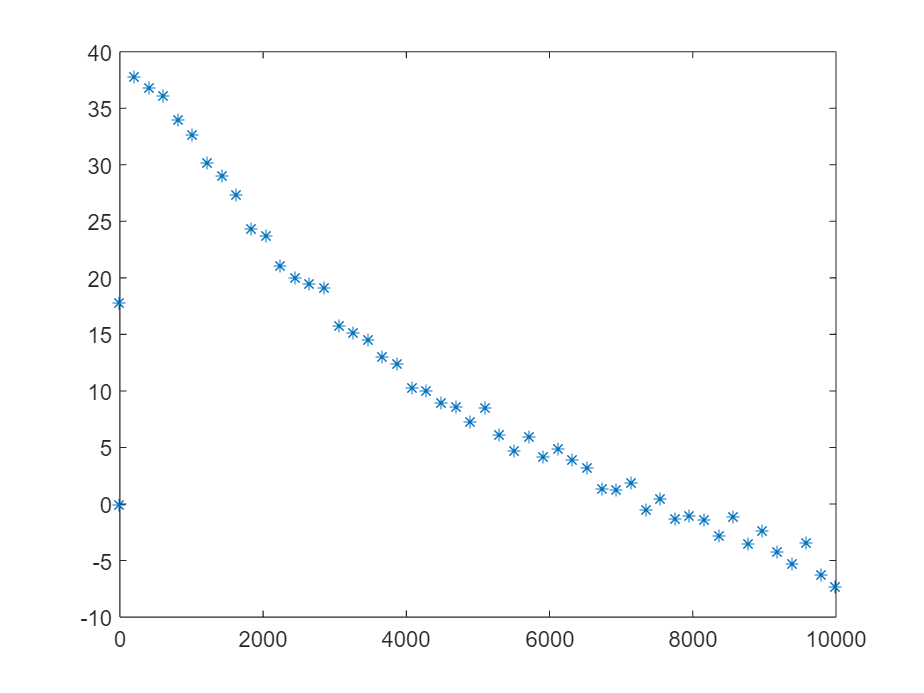

plot(bodeTable(:,1), bodeTable(:,3), "*")

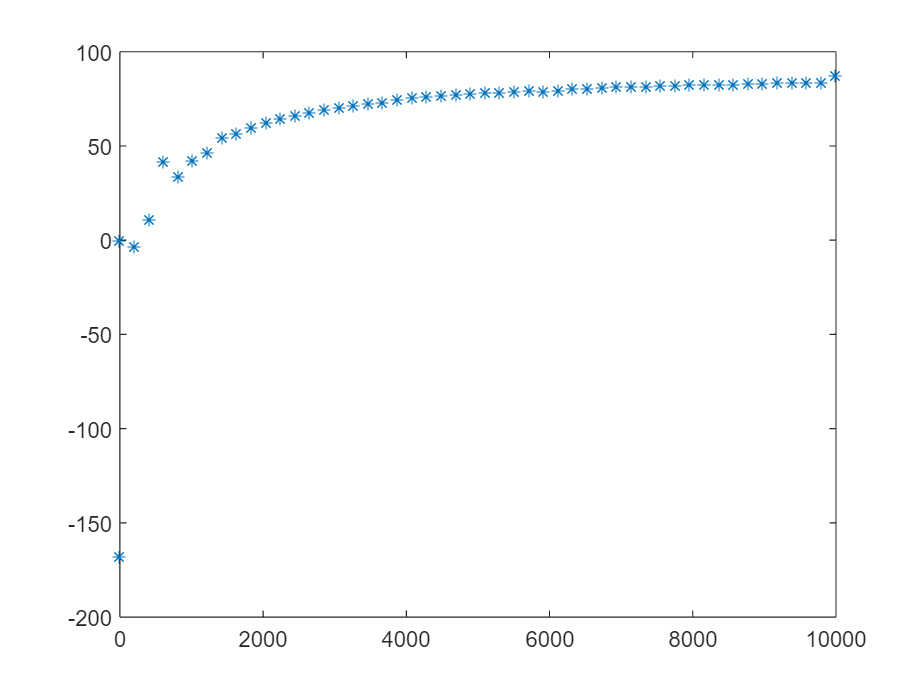

plot(bodeTable(:,1), bodeTable(:,5), "*")

function PhDiff = phdiffmeasure(x, y)
% represent the signals as column-vectors
 x = x(:);
 y = y(:);
% remove the DC component of the signals
x = x - mean(x);
y = y - mean(y);

% signals length calculation
xlen = length(x);
ylen = length(y);

% windows generation
xwin = hanning(xlen, 'periodic');
ywin = hanning(ylen, 'periodic');

% perform fft on the signals
X = fft(x.*xwin); 
Y = fft(y.*ywin);

% fundamental frequency detection
[~, indx] = max(abs(X));
[~, indy] = max(abs(Y));

% phase difference estimation
PhDiff = angle(Y(indy)) - angle(X(indx));

end 
